# Ex01. STLファイルの読み込み

この章では、STLファイルを読み込み、モデルを表示します。

この章はチュートリアル形式なので課題はありません。Ex02以降の課題の参考にしてください。

## 1. 実行環境の確認

プログラムを正しく動かすため、”現在のフォルダー” が "Ex01" になっていることを確認してください。

MATLABウィンドウ左側の "現在のフォルダー" にて、画像のように "Ex01" フォルダーの中身のみが表示されていればOKです。

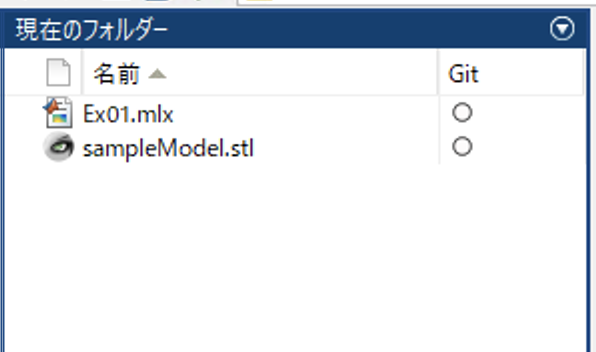

他の場所が表示されている場合は、ウィンドウ上部の "Ex01.mlx" と表示されているタブを右クリックし、

一番上の "現在のフォルダーを C:¥...¥Ex_3DRadon¥Ex01 に変更" を選択してください。

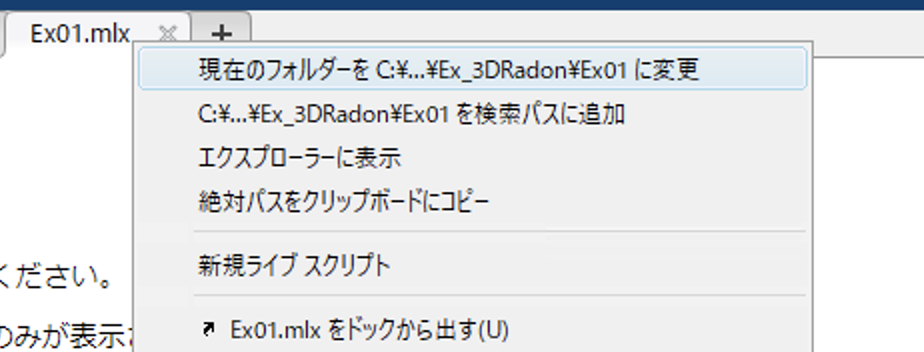

Ex02以降の章でも、必ず同様に、その章のみのフォルダ内で作業してください。

他のフォルダのファイルが誤って呼び出されることを防ぎます。

## 2. STLファイルの読み込み

STLファイルは、ファイル拡張子が .stl であるファイルで、3Dモデルの形状データを表します。

3Dデータを表すファイル形式には様々なものがありますが、STLファイルは最もシンプルな形式の一つで、世界中で広く使われています。

それでは早速、STLデータを読み込むプログラムを書いてみましょう。

MATLABにはSTLデータを読み込む関数 [stlread](https://jp.mathworks.com/help/matlab/ref/stlread.html) が用意されています。

ウィンドウ上部の実行ボタンを押して、次のコードを実行してみましょう。

clear % ワークスペースの初期化

file_path = "sampleModel.stl";
TR = stlread(file_path);

ウィンドウ左のワークスペース内に、”TR”という名前の変数が追加されていれば読み取り成功です。

## 3. 読み取り結果の確認

変数 "TR" の中身を見てみましょう。

ウィンドウ左のワークスペースから、”TR” をダブルクリックで開いてみてください。

変数ウィンドウが開き、TRの中身が表示できたと思います。

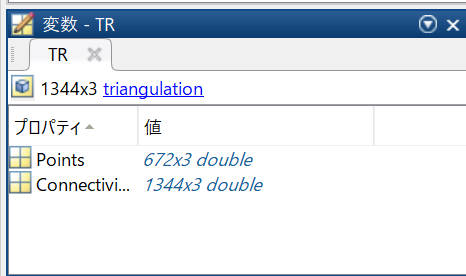

TRは [triangulation](https://jp.mathworks.com/help/matlab/ref/triangulation.html) という型のオブジェクトで、Points と ConnectivityList という2つのプロパティを持っていることがわかります。

この triangulation とは、簡単に言うと「三角形の集合」です。

STLファイルは3Dモデルの表面を、小さな三角形のあつまりで表現しています。

表面全体をメッシュ(mesh)、それぞれの三角形をパッチ(patch)と呼びます。

変数ウィンドウで Points や ConnectivityList をさらにダブルクリックすると、それらの中身も見ることができます。

プログラムでは以下のように "." でプロパティ名をつなげることで、各プロパティにアクセスできます。

% Pointsの配列サイズを見る
size(TR.Points)

ans =    672     3


% ConnectivityListの最初の行を見る
TR.ConnectivityList(1,:)

ans =      1     2     3


これらの値の意味については、[公式ドキュメントのtriangulationのプロパティの説明](https://jp.mathworks.com/help/matlab/ref/triangulation.html#d123e1079165) に書いてあります。

具体的に見てみましょう。

まずは ConnectivityList です。

% ConnectivityListの最初の5行を見る
TR.ConnectivityList(1:5,:)

ans =      1     2     3
     3     2     4
     3     4     5
     6     7     1
     1     7     8


ConnectivityList の各行は1つの三角形を表現しています。

1行目より、1つ目の三角形は 点1・点2・点3 を頂点に持っていることがわかります。

同様に、2つ目の三角形は 点3・点2・点4 を頂点に持っています。

この2つの三角形は2点を共有しているので、隣接した三角形だとわかります。

% ConnectivityListの配列サイズを見る
size(TR.ConnectivityList)

ans =         1344           3


配列の行数から、この3Dモデルは1344枚の三角形で表現されていることがわかります。

つぎに Points についても見てみます。

% Pointsの最初の5行を見る
TR.Points(1:5,:)

ans =   168.1657   16.6684   60.1708
  134.7761   16.6684   72.9808
  125.0384   16.6684   60.1708
  132.8853   16.6684   72.1976
  130.8562   16.6684   71.9305


Points の各行は1つの点の座標を表しています。

1行目より、点1は (x,y,z) = (168.1657, 16.6684, 60.1708) にあることがわかります。

これらの値をもとに、初めの3枚の三角形がどのような形状か表示してみましょう。

tri1 = TR.Points(TR.ConnectivityList(1,:),:)

tri1 =   168.1657   16.6684   60.1708
  134.7761   16.6684   72.9808
  125.0384   16.6684   60.1708


tri2 = TR.Points(TR.ConnectivityList(2,:),:)

tri2 =   125.0384   16.6684   60.1708
  134.7761   16.6684   72.9808
  132.8853   16.6684   72.1976


tri3 = TR.Points(TR.ConnectivityList(3,:),:)

tri3 =   125.0384   16.6684   60.1708
  132.8853   16.6684   72.1976
  130.8562   16.6684   71.9305


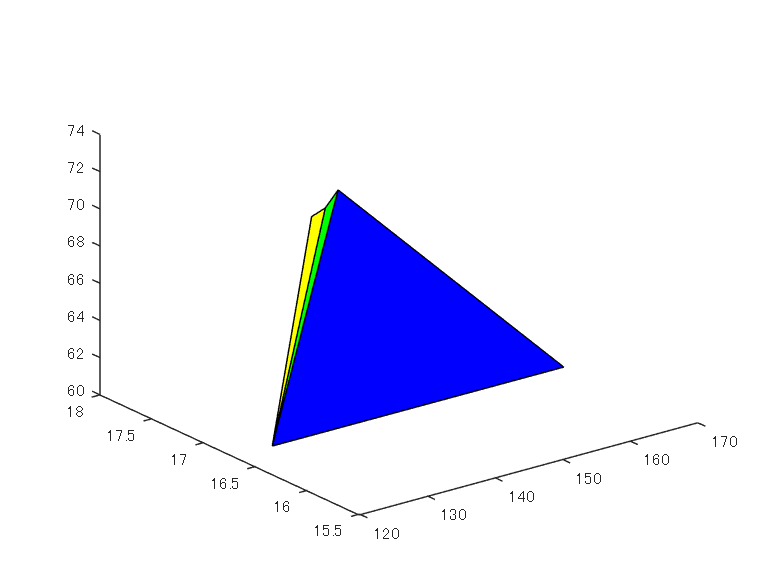

figure
fill3(tri1(:,1), tri1(:,2), tri1(:,3), 'blue') % 1枚めの三角形
hold on % グラフにまだ追加することを宣言
fill3(tri2(:,1), tri2(:,2), tri2(:,3), 'green') % 2枚めの三角形
fill3(tri3(:,1), tri3(:,2), tri3(:,3), 'yellow') % 2枚めの三角形

グラフ上のアイコンを選ぶと、グラフの回転や拡大・縮小をできます。

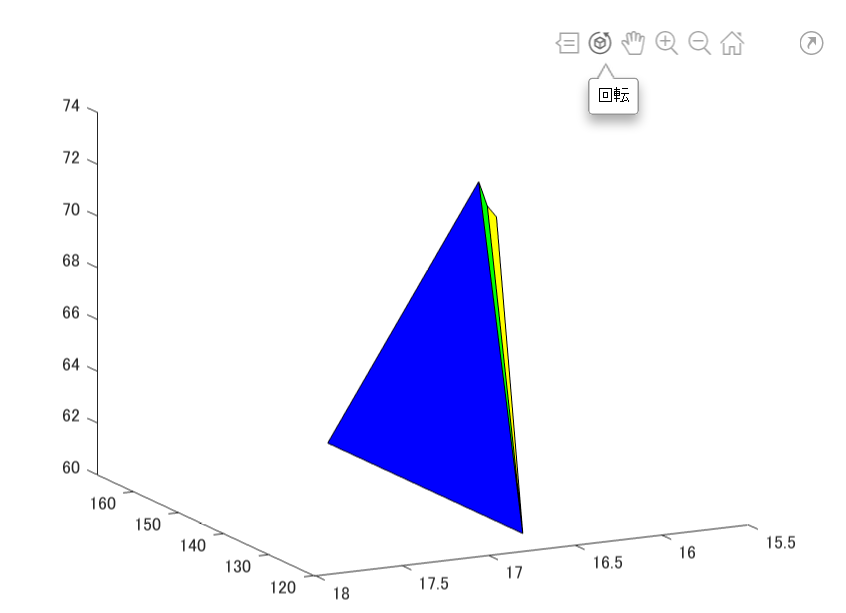

## 4. 3Dモデルの表示

それでは最後に、読み取った3Dモデルを表示して、形状を確認してみましょう。

MATLABには triangulation を表示する関数 [trisurf](https://jp.mathworks.com/help/matlab/ref/trisurf.html) が用意されています。

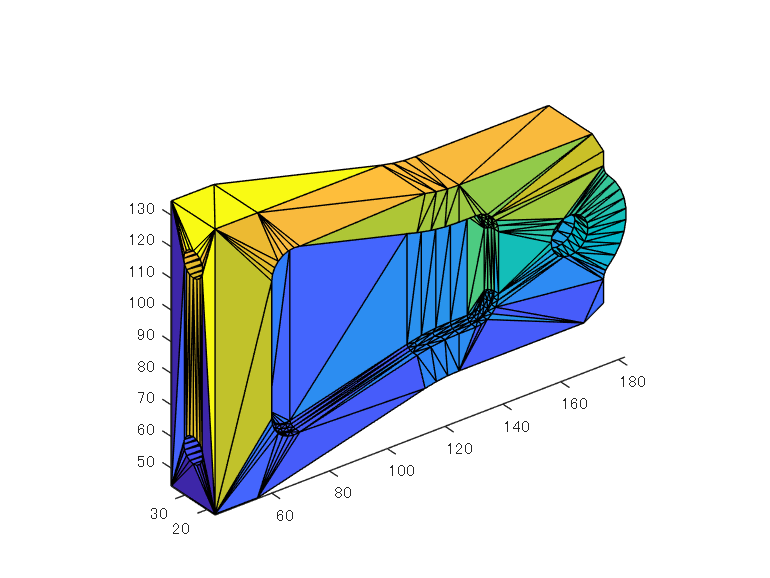

trisurf(TR)
axis equal % XYZの目盛りを1:1:1に